# **Graph Theory Algorithm Discussion**

This demo will guide you through some of the trickier graph algorithms of the current homework assignment.

## **Detecting Cycles in a Graph**

### Potential Strategy

One approach to detect cycles is to "prune all *leaves* of a graph", where a **leaf** is any vertex connected to 1 or fewer edges.

This involves repeatedly removing all vertices connected to 1 or fewer edges until no "leaves" are left. If there are any remaining vertices, they must form part of a cycle.

Algorithm in Pseudo-code:

### **Example 1: Graph with a Cycle**

Consider a graph with 3 vertices and 3 edges represented by:

G1.edges = [
    1 2;
    2 3;
    3 2;
];
G1.n = 3;

Visualize the graph

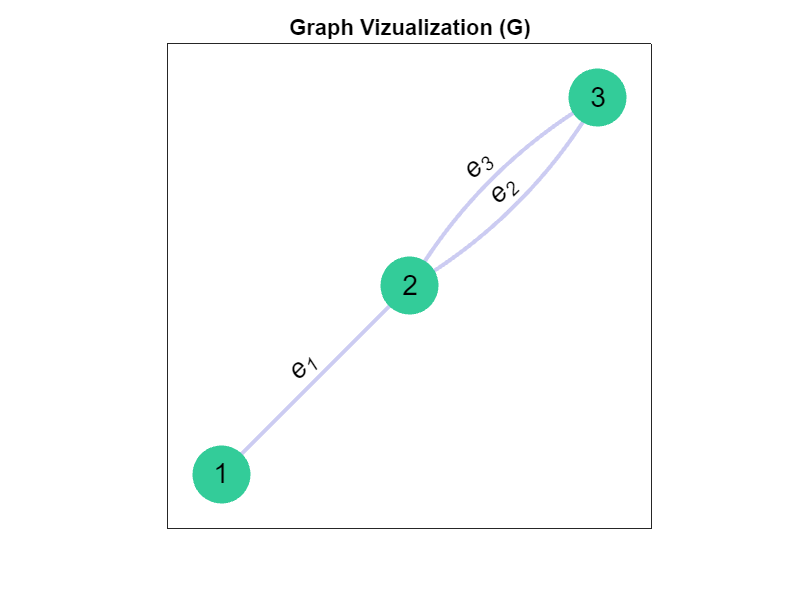

visualize_graph(G1);

Create adjacency matrix

A = HW5P1_adjacency_matrix(G1);
disp(table(A))

         A     
    ___________

    0    1    0
    1    0    2
    0    2    0



Step-by-Step Pruning

Since the 1st row of `A` is a leaf, we remove it from `A`.

A(1,:) = []; A(:,1) = [];
disp(table(A))

      A   
    ______

    0    2
    2    0



Since `A` has no more leaves and there are still vertices left in `A`, `G` must have a cycle.

### **Example 2: Graph without a Cycle**

Consider a graph without cycles represented by:

G2.edges = [
    1 2;
    2 4;
    4 5;
    4 6;
];
G2.n = 6;

Visualize the graph

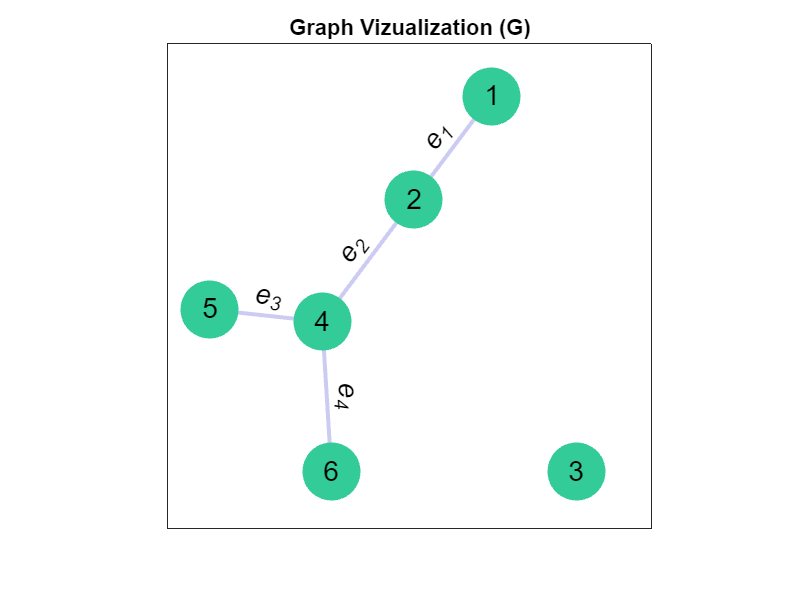

visualize_graph(G2);

Create adjacency matrix

A = HW5P1_adjacency_matrix(G2);
disp(table(A))

                A             
    __________________________

    0    1    0    0    0    0
    1    0    0    1    0    0
    0    0    0    0    0    0
    0    1    0    0    1    1
    0    0    0    1    0    0
    0    0    0    1    0    0



Step-by-Step Pruning

Since the vertex in the 1st row is a leaf, remove the vertex.

A(1,:) = []; A(:,1) = [];
disp(table(A))

              A          
    _____________________

    0    0    1    0    0
    0    0    0    0    0
    1    0    0    1    1
    0    0    1    0    0
    0    0    1    0    0



Since the vertex in the 1st row is a leaf, remove the vertex.

A(1,:) = []; A(:,1) = [];
disp(table(A))

           A        
    ________________

    0    0    0    0
    0    0    1    1
    0    1    0    0
    0    1    0    0



Continue removing leaves

A(1,:) = []; A(:,1) = [];
disp(table(A))

         A     
    ___________

    0    1    1
    1    0    0
    1    0    0



A(2,:) = []; A(:,2) = [];
disp(table(A))

      A   
    ______

    0    1
    1    0



A(1,:) = []; A(:,1) = [];
disp(table(A))

    A
    _

    0



A(1,:) = []; A(:,1) = [];
disp(table(A))

    A
    _




Since `A` is empty, there are no cycles in `G`.

## **Detecting Connectivity in a Graph**

### Potential Strategy

A common way to determine if a graph is connected is to start from an arbitrary vertex and explore all reachable vertices using a queuing technique.

If all vertices are reachable from this starting point, then the graph is connected. Otherwise, it is not connected.

Key Variables:

- `visited`: Keeps track of whether each vertex has been visited.

- `queue`: Stores vertices to be explored next.

- `neighbors`: Stores the adjacent vertices of the current vertex.

Algorithm in Pseudo-code:

### **Example 1: Connected Graph**

Consider a connected graph with 4 vertices and edges given by:

G1.edges = [
    1 2;
    2 3;
    3 4;
    4 1;
];
G1.n = 4;

Visualize the graph

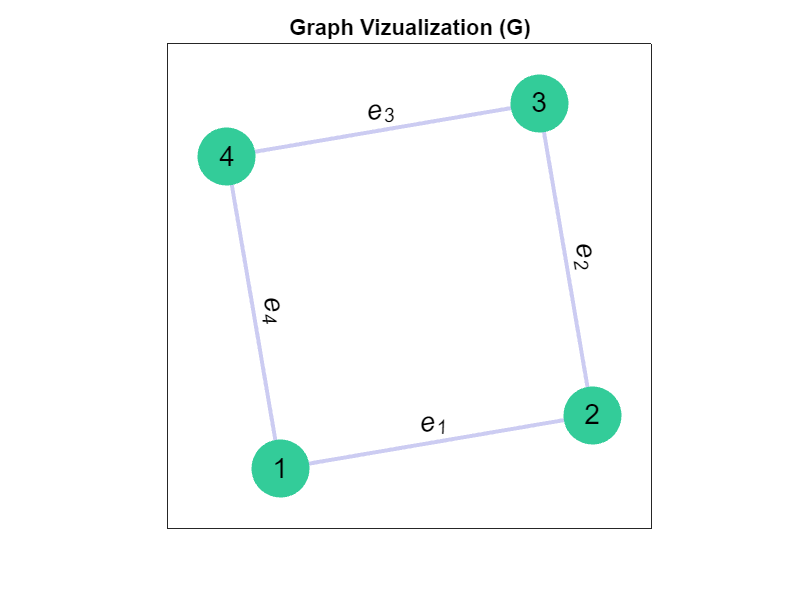

visualize_graph(G1);

% Initialize variables
visited = false(1, G1.n);   % Track visited nodes
queue = 1;                  % Start from vertex 1

disp('Starting traversal for connectivity check (Example 1):')

Starting traversal for connectivity check (Example 1):



count = 1;

while ~isempty(queue)
    fprintf('\nLoop %i\n', count);
    fprintf('\n\tCurrent queue: %s\n', mat2str(queue));
    next = queue(1);
    visited(next) = true;  % Mark the current node as visited
    fprintf('\tVisited nodes: %s\n', mat2str(visited));
    
    % Remove the current node from the queue
    queue(1) = [];
    
    % Find neighbors of the current node
    neighbors = HW5P5_get_neighbors(next, G1);
    fprintf('\tNeighbors of node %d: %s\n', next, mat2str(neighbors));
    
    % Add unvisited neighbors to the queue
    for neighbor = neighbors
        if ~visited(neighbor)
            queue(end+1) = neighbor;
        end
    end
    
    % Display the updated queue
    fprintf('\tUpdated queue after visiting node %d: %s\n', next, mat2str(queue));
    count = count + 1;
end


Loop 1



	Current queue: 1


	Visited nodes: [true false false false]


Unrecognized field name "adj_mat".

Error in HW5P5_get_neighbors (line 2)
    vertices = 1:height(G.adj_mat);


% Final check for connectivity
is_connected1 = sum(~visited) == 0;
disp(['Example 1 Result: The graph is connected: ', num2str(is_connected1)])

### **Example 2: Disconnected Graph**

Consider a disconnected graph with 5 vertices, where two separate clusters exist:

G2.edges = [
    1 2;
    2 3;
    4 5;
];
G2.n = 5;

Visualize the graph

visualize_graph(G2);

% Initialize variables
visited = false(1, G2.n);   % Track visited nodes
queue = 1;                  % Start from vertex 1

disp('Starting traversal for connectivity check (Example 2):')

count = 1;

while ~isempty(queue)
    fprintf('\nLoop %i\n', count);
    fprintf('\n\tCurrent queue: %s\n', mat2str(queue));
    next = queue(1);
    visited(next) = true;  % Mark the current node as visited
    fprintf('\tVisited nodes: %s\n', mat2str(visited));
    
    % Remove the current node from the queue
    queue(1) = [];
    
    % Find neighbors of the current node
    neighbors = HW5P5_get_neighbors(next, G2);
    fprintf('\tNeighbors of node %d: %s\n', next, mat2str(neighbors));
    
    % Add unvisited neighbors to the queue
    for neighbor = neighbors
        if ~visited(neighbor)
            queue(end+1) = neighbor;
        end
    end
    
    % Display the updated queue
    fprintf('\tUpdated queue after visiting node %d: %s\n', next, mat2str(queue));
    count = count + 1;
end

% Final check for connectivity
is_connected2 = sum(~visited) == 0;
disp(['Example 2 Result: The graph is connected: ', num2str(is_connected2)])